# Temperature plot

this code is to plot calcium imaging signals responding to temperature changes

#### Read Table and plot heatmap

close all
clearvars -except path
% addpath('C:\Users\Qi_Li\Dropbox (HMS)\code\LQ_calcium_matlab');
fps = 10; % frequency in Hz, change this when using different settings

if exist('path', 'var') == 0 || isempty(path) || ~ischar(path)
    [filename,path] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Rig\calcium\*.csv');
else
    [filename, path] = uigetfile(fullfile(path,'*.csv'));
end

% initialPlot is a function for us to get a first and general idea of how
% the data looks like. Bleach correction is only suggested when the
% calcium spikes are short or when the recording session is longer than
% 120s

normDeltaF = initialProcess(path, filename, fps, 'bleach correction', 6, 0.975);

Error using readtable (line 517)
Unable to find or open '□\□'. Check the path and filename or file permissions.

Error in initialProcess (line 13)
A1 = table2array(readtable(fullfile(path, filename)));

%normDeltaF = initialProcess(path, filename, fps);


#### If happy with the figure, save it

if (1)
    pathparts = strsplit(path,filesep);
    mouseID = pathparts{end-1}; clear pathparts
    name = [filename(1:end-4), '_', mouseID];
    t = title(name);
    set(t,'Interpreter','none')
    
    figureName = [path, name, '.jpg'];
    saveas(gcf,figureName)
    clear t
end

#### **Align with pre-defined temperature setting**

%Set temperature here
Temperature = [linspace(25,32,2*fps), repmat(32, 1, 20*fps), linspace(32,0,6.4*fps), repmat(0, 1, 23.6*fps), linspace(0,32,6.4*fps)];
%plot(Temperature)

%split the recording file if needed
normDeltaF = normDeltaF(1:600,:);

%hard coded baseline duration based on temperature setting
NewnormDeltaF = normDeltaF(:,:) - mean(normDeltaF(2*fps:22*fps,:));
meanResponse = mean(NewnormDeltaF(22*fps:52*fps,:),1)


[~, sortOrder] = sort(meanResponse, 'descend');
Sorted_response_ori = normDeltaF(:,sortOrder);
Sorted_response = NewnormDeltaF(:,sortOrder);
%filter cell if needed
%Sorted_response = Sorted_response(:,5:end);
Max = sort(max(NewnormDeltaF));
MaxLimit = max(Max);
if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end

nCell = size(Sorted_response,2);

fig = figure
fig.Position = [100 100 800 400];   % 800 × 400 pixels
tiledlayout(5,1,'TileSpacing','compact','Padding','compact');
% Temperature line
ax1 = nexttile([1 1]);
plot(Temperature, 'LineWidth', 1.5);
ylabel('Temp (°C)');
title('Temperature & Calcium Activity');
grid off;
box(ax1,'off');
set(ax1, 'XTickLabel', []);      % hide top x-axis labels to share with heatmap
hold on;
text(110, 32, '  32', 'FontWeight','bold', 'VerticalAlignment','bottom', 'Clipping','on');
text(402, 0, '0', 'FontWeight','bold', 'VerticalAlignment','bottom', 'Clipping','on');
% Calcium heatmap
ax2 = nexttile([4 1]);
imagesc(Sorted_response');           % transpose so cells are on y-axis
set(gca, 'YDir','reverse');
%axis xy;                         % put cell # increasing upward
xticks(100:100:600);
timelabel = strsplit(num2str(100/fps:100/fps:600/fps));
xticklabels(timelabel); xlabel("time (s)")
yticks(5:5:nCell);
xlabel('Time (s)');
ylabel('Cell');
cb = colorbar; cb.Label.String = 'Calcium Intensity';
colormap(turbo);                 % nice perceptual colormap

% Link x-axes so zoom/pan together
linkaxes([ax1, ax2], 'x');

caxis([0 Limit])


%Save figures & responses
output_name = 'Heatmap Plot of cell responses.pdf';
output_path = fullfile(path,output_name);
exportgraphics(fig, output_path, 'ContentType', 'vector', "Resolution",800);
sortedfilename_output = strcat(extractBetween(path, 'calcium\', '\preprocess'), '_sorted_data.mat');
sortedfilename_output = sortedfilename_output{1};
sortedfilename_output = strrep(sortedfilename_output, '\', '_');
save(fullfile(path, sortedfilename_output), 'Sorted_response')

#### **Load multiple analyzed files**

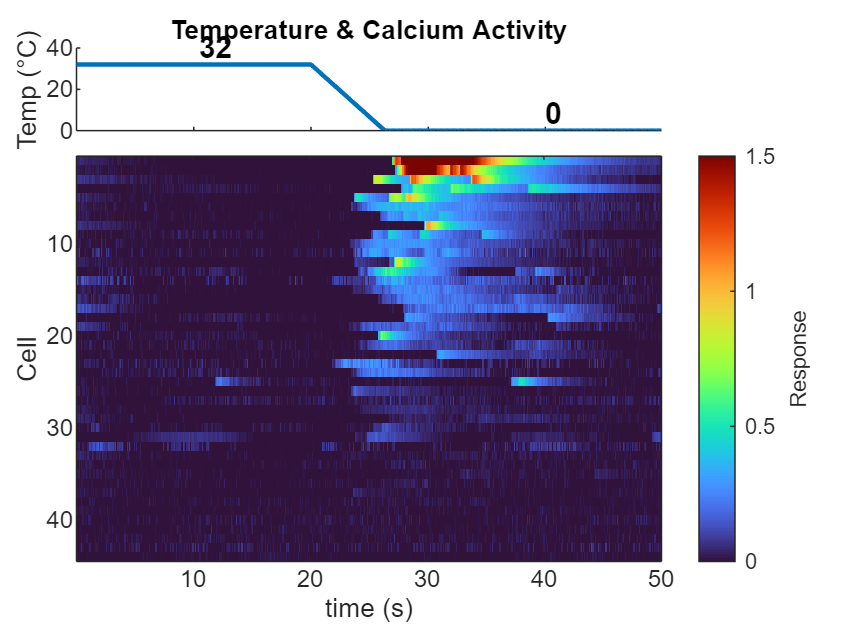

clear;
fps= 10;
[filenames,path] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Rig\calcium\*.mat','MultiSelect','on');
allData = cell(numel(filenames),1);
for i = 1:numel(filenames)
    temp = load(fullfile(path,filenames{i}));
    allData{i} = temp.Sorted_response;
end
Allresponse = cat(2, allData{:});

%sort again
meanAllResponse = mean(Allresponse(22*fps:52*fps,:),1);
[~, sortAllOrder] = sort(meanAllResponse, 'descend');
sortedAll = Allresponse(:,sortAllOrder);
Temperature = [repmat(32, 1, 20*fps), linspace(32,0,6.4*fps), repmat(0, 1, 23.6*fps)];%[repmat(32, 1, 20*fps), linspace(32,0,6.4*fps), repmat(0, 1, 23.6*fps), linspace(0,32,6.4*fps),repmat(32,1,1.6*fps)];
t = (0:size(Temperature,2)-1)/fps;
%Trim the data to show only the 32 and 0 not the decrease.
sortedAll = sortedAll((2*fps+1):52*fps,:);

%plot all
fig = figure;
tiledlayout(5,1,'TileSpacing','compact','Padding','compact');
% Temperature line
ax1 = nexttile([1 1]);
plot(t,Temperature, 'LineWidth', 1.5);
xlim([0 t(end)]);
ylabel('Temp (°C)');
title('Temperature & Calcium Activity');
grid off;
box(ax1,'off');
set(ax1, 'XTickLabel', []);      % hide top x-axis labels to share with heatmap
hold on;
text(9, 32, '  32', 'FontWeight','bold', 'VerticalAlignment','bottom', 'Clipping','on');
text(40, 0, '0', 'FontWeight','bold', 'VerticalAlignment','bottom', 'Clipping','on');
% Calcium heatmap
ax2 = nexttile([4 1]);
imagesc(sortedAll');         % transpose so cells are on y-axis
axis xy;
set(gca, 'YDir','reverse');
xlabel('Time(s)');
ylabel('Cell');
xticks(100:100:580);
timelabel = strsplit(num2str(100/fps:100/fps:580/fps));
xticklabels(timelabel); xlabel("time (s)")
yticks(10:10:size(sortedAll,2));


cb = colorbar; cb.Label.String = 'Response';
colormap(turbo);
caxis([0 1.5]);

%save plots
output_name = 'Heatmap Plot of cell responses.pdf';
output_path = fullfile(path,output_name);
exportgraphics(fig, output_path, 'ContentType', 'vector', "Resolution",800);

#### Previous codes: Save into structure called 'Data'

save the data into structure so it's easier to access in the future

structName = [path, 'Data.mat'];
if isfile(structName)
    load(structName);
else
    Data = struct;
    %data.info.mouseID = mouseID;
end

if contains(filename,"frey")  % the fieldname can't start with number
    filename = erase(filename, "von_frey");
    filename = strcat('von_frey',filename);    
end

Data.(filename(1:end-4)) =  normDeltaF;

save(structName, 'Data');

clear structName

#### Quatification and save the responsive ROIs into a structure

nStd = 5;%7; 
% the signal that is 'nStd' times of of standard deviation larger than noise (in baseline) is regarded as response 
% nStd can change depending on the sigal-to-noise ratio of imaging
% the baseline is the first 90 or 100 frames of the imaging averaged
[digitROI, responseROI0] = quantify(normDeltaF, filename, nStd);

#### Plot traces of all responsive neurons

thresh = 0.1; 
spike0 = plotAllResponse(responseROI0, normDeltaF,path, filename, thresh, fps, ...
    "peakLabel", 1, 'NumFig', 60, 'save',0); 
% if "peakLabel" is 1, peaks will be labeled
% the spike0 contains the amplitude and timing of the peaks

#### Save the response information into two structure

% goodROI = [1, 2, 5, 7, 8, 10, 11, 20, 21, 24, 25, 26, 27 ]; badROI = setdiff(responseROI0, goodROI);
badROI = [];
[responseROI, responseIndex] = setdiff(responseROI0, badROI);
responseROI(2, :) = nStd; % nStd means the definition of response, stored in second line of responseROI
responseROI(3, 1:length(badROI)) = badROI;
spike = spike0(:, responseIndex,:);
% clear spike0 responseROI0

responseStructName = [path, 'responseROIstruct.mat'];
if isfile(responseStructName)
    load(responseStructName);
else
    responseROIstruct = struct;
end

responseROIstruct.(filename(1:end-4)) = responseROI;
% responseROIstruct.(filename(1:end-5)) = responseROI;

save(responseStructName, 'responseROIstruct');

spikeStructName = [path, 'spikeStruct.mat'];
if isfile(spikeStructName)
    load(spikeStructName);
else
    spikeStruct = struct;
end

spikeStruct.(filename(1:end-4)) = spike;
save(spikeStructName, 'spikeStruct');

#### Plot traces of certain neuron (optional)

If curious about what certain trace looks like, or what does bleach correction algorithm do to the trace


nCell = input('the neuron you are interesed in?  \n ');
figure,
subplot(211);
plot(normDeltaF(:,nCell)), title(['DeltaF/F of Cell ', num2str(nCell)]);
box off
% subplot(212),findpeaks(normDeltaF(:,nCell),'MinPeakProminence',thresh),title('Peaks');
[~, b, ~] = RobustDetrend(normDeltaF(:,nCell), 6, 0.975);
subplot(212), plot(b), 
title(['DeltaF/F of Cell ', num2str(nCell), ' bleach corrected']);
box off
